# BouncingBallAcousticAnalysis

Analyzes mobile phone audio recording of a ball bouncing on a concrete+tile surface. The bounce sounds depend upon the surface and are located in time using cross correlation. The ratios of successive time intervals are used to measure the coefficient of restitution as a function of bounce time interval.

Author: Duncan Carlsmith

## Read in and examine audio file. 

Read audio data using function [audioread](https://www.mathworks.com/help/matlab/ref/audioread.html).  We catch a vector `ys` of audio signals and the sampling frequency `fs`.

**Try this**: Comment out the files you do not want to read.

clear
fln='BouncingPingPongBall1m.m4a';ifile=0;
% fln='MultiplePingPongBalls.m4a';ifile=1;
% fln='SuperballRepeat.m4a';ifile=2;
fln='PingpongBallCountertop.m4a';ifile=3;
[ys,fs]=audioread(fln);% ys is the signal, fs the sample rate.

 For stereo audio, `ys` will be a 2 column array of "left" and "right" signals so, just in case, let's use just the first column.

ys=ys(:,1);

Play the sound.

%sound(ys,fs);

Compute a vector of times using the sample rate and plot the data.

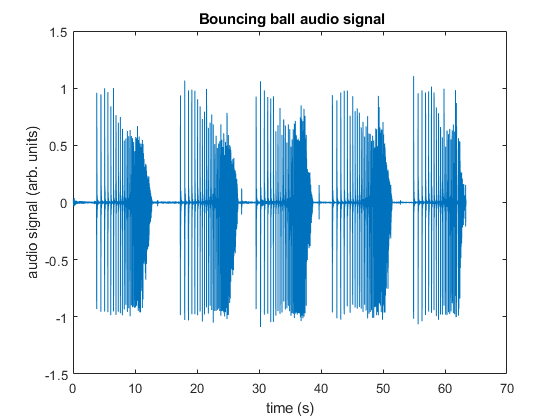

ts=[1:length(ys)]*1.0/fs -1.0/fs;% times in s starting at 0
figure
plot(ts,ys); 
hold on
xlabel('time (s)');ylabel('audio signal (arb. units)')
title(' Bouncing ball audio signal')

Notice that an audio signal is typically a double with values ranging from minus one to plus one. Typically the [bit depth](https://en.wikipedia.org/wiki/Audio_bit_depth) that ultimately limts the precision of the audio samples is 16-bits.

### Hand select clean data.

Pick start and end time in s. 

if ifile==0
    t1=2.2;% start time (s)
    t2=14.0;% end time (s)
end
if ifile==1
    t1=2.2;% start time (s)
    t2=42.0;% end time (s)
end
if ifile==2
    t1=3;% start time (s)
    t2=60.0;% end time (s)
end
if ifile==3
    t1=2.2;% start time (s)
    t2=60.0;% end time (s)
end

Round times in seconds in units of sampling time towards zero to obtain integer indices.

I1=fix(t1*fs);I2=fix(t2*fs);

Define selected data and times and superpose on data plot.

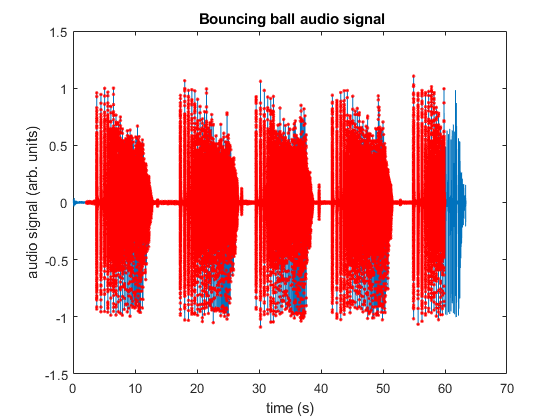

y=ys(I1:I2);
t=ts(I1:I2);
hold on;
plot(t,y,'r.')

The sequences of pulses resulting from bouncing are clearly seen atop a background of room noise and reverberation after each pulse.

### Perform Fourier analysis and remove low frequency noise

Get the power spectrum using [pspectrum](https://www.mathworks.com/help/signal/ref/pspectrum.html). We call the function and catch a vector of power `p` and corresponding vector of  frequencies `f`.

[p,f]=pspectrum(y,fs);
figure

Plot the power spectrum on a loglog scale using [loglog](https://www.mathworks.com/help/matlab/ref/loglog.html?searchHighlight=loglog&s_tid=doc_srchtitle).

loglog(f, p,'b');% plot power versus frequency for pspectrum
xlim([3000, 20000]) ;

Apply a bandpass filter using [bandpass](https://www.mathworks.com/help/signal/ref/bandpass.html) with lower limit 5kHz and upper limit 20kHz with  60 db attenuation to reduce room noise.

lowf=5000;highf=20000; % frequency range limits
yf=bandpass(y,[lowf,highf],fs,'StopbandAttenuation',60);

Overlay the power spectrum after application of the filter.

[p,f]=pspectrum(yf,fs);
hold on
loglog(f, p,'r');
xlabel('Frequency (Hz)');ylabel('Power (arb units)');
title('Power spectrum of bouncing ball data')

Add a legend letting MATLAB choose a best location so it does not obscure the data.

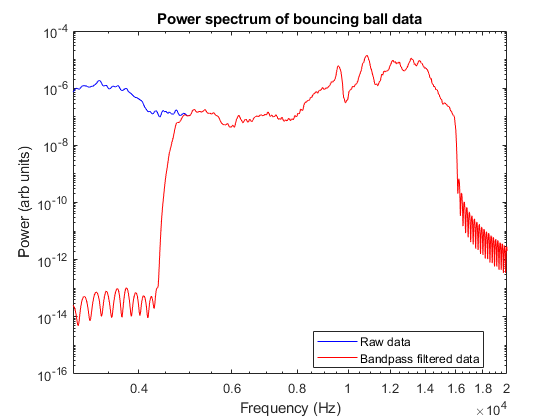

legend('Raw data','Bandpass filtered data','Location',"best")
hold off

Plot the data again, now after application of the bandpass filter.

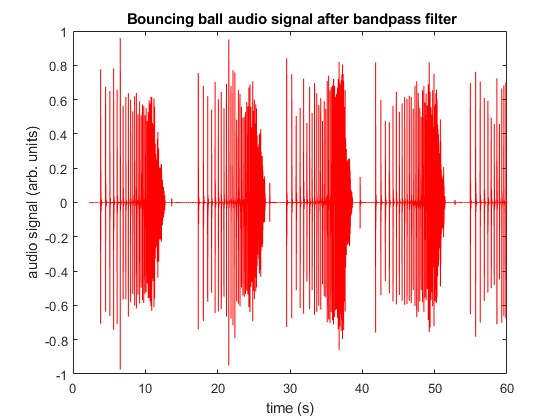

figure
plot(t,yf,'r')
xlabel('time (s)');ylabel('audio signal (arb. units)')
title(' Bouncing ball audio signal after bandpass filter')

We observe the background noise between bounces is suppressed. Interestingly, the peak audio amplitude is a decreasing but not smooth function of bounce number. This might reflect irregularity in the floor or ball as well as distance from the microphone.

### Select largest bounce as a template for bounce audio signal.

Plot a representative single bounce, a small range of time around the highest value of the filtered signal. Use [max](https://www.mathworks.com/help/matlab/ref/max.html) to find this highest bounce signal.

range=0.00156;% half range in s
[ymax,I] = max(yf,[],'linear');
I/fs+t(1)-1/fs;

Max returns the max value and index (location) in the data yf.

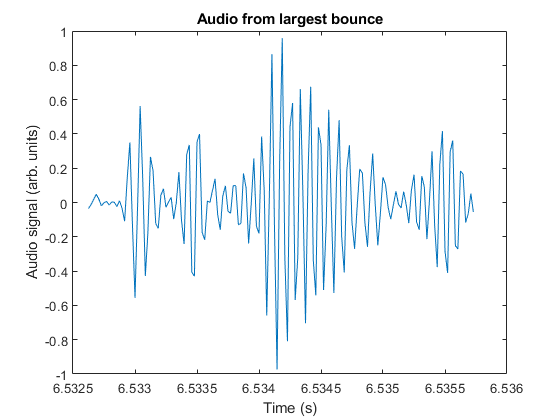

I1=fix(I-fs*range);
I2=fix(I+fs*range);
ybounce=yf(I1:I2);tbounce=t(I1:I2);
Ybounce=yf;
Ybounce(1:I1-1)=0;Ybounce(I2+1:end)=0; % entire signal windowed on template pulse
figure
plot(tbounce,ybounce)
xlabel('Time (s)');ylabel('Audio signal (arb. units)')
title('Audio from largest bounce')

Plot a somewhat longer version.

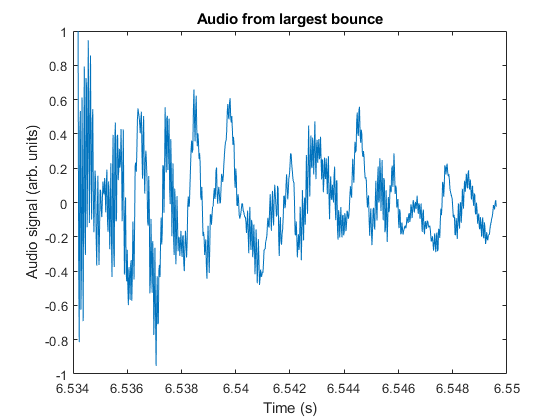

figure
I1long=I;I2long=I+10*(I2-I);
tbouncelong=t(I1long:I2long); ybouncelong=y(I1long:I2long);
plot(tbouncelong,ybouncelong)
xlabel('Time (s)');ylabel('Audio signal (arb. units)')
title('Audio from largest bounce')

The shape of the acoustic pulse depends upon the ball and the surface it impacts. One sees some evidence for echos merging into chaotic reverberation in the room decaying in amplitude with a mean time of order milliseconds.

Plot frequency spectrum of largest bounce.

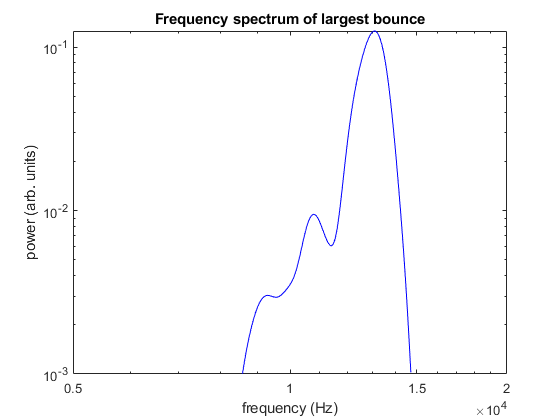

[p,f]=pspectrum(ybounce,fs);
figure
loglog(f(p>1e-3), p(p>1e-3),'b');% plot power versus frequency for pspectrum
xlim([lowf, highf]) ;
xlabel('frequency (Hz)');ylabel('power (arb. units)')
title('Frequency spectrum of largest bounce')

We observe peaks near 10 kHz which may corespond to the inverse of the collision time convolved with the spectral response of the floor.

### Cross correlate template signal with the data to locate bounce signals

Cross correlate the template signal with the data using [xcorr](https://www.mathworks.com/help/matlab/ref/xcorr.html). See [Find a signal in a measurement.](https://www.mathworks.com/help/signal/ug/find-a-signal-in-a-measurement.html) The `xcorr` command that follows pads the template snippet `ybounce` to the length of the filtered data yf with zeros and then takes the inner product of `yf` and `ybounce` at all possible locations of `ybounce` within `yf`. (In the inner product, ybounce is zero for times outside its range.) Where ybounce overlaps a similar signal, the cross correlation is large. The xcorr function returns a vector of cross correlation  values and a vector of corresponding time delays, both of twice the length of the filtered data. These delays provide a measure of the occurance times of bounces.

[xCorrall,lagsall] = xcorr(yf,ybounce);

Translate the lag times of the cross correlation to times used to describe the data.

tCorrall=t(1)+lagsall'/fs;

Normalize the cross correlation to unity at its largest absolute value.

xCorrall=xCorrall/max(abs(xCorrall));
% figure
% plot(tCorrall,xCorrall)
% grid
% xlabel('Time (s)')
% ylabel('Correlation (arb. units)')
% axis tight

The cross correlation vectors are twice as long as the filtered data. Use only the physical half.

xCorr=xCorrall(tCorrall>0);
tCorr=tCorrall(tCorrall>0);

Plot the correlation values versus time delay.

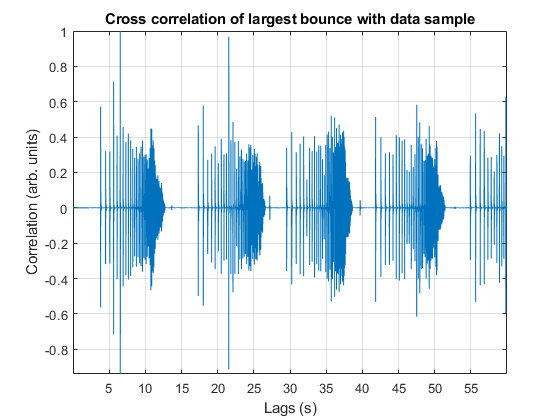

plot(tCorr,xCorr)
grid
xlabel('Lags (s)')
ylabel('Correlation (arb. units)')
title('Cross correlation of largest bounce with data sample')
axis tight

### Find peaks in the cross correlation and identify them as the bounce times.

Use [findpeaks](https://www.mathworks.com/help/signal/ref/findpeaks.html) to identify the bounce times in the cross correlation data. The `findpeaks` algorithm searches for the highest peak within constraints designed to identify bounces, and plots the data, indicating the locations of the found peaks with triangles. 

We need to set parameters for `findpeaks` to best identify signals above noise level but not find spurious peaks. We will do this "by hand."

Histogram `xCorr `small values to look at noise level.

% figure
% histfit(xCorr(abs(xCorr)<rms(xCorr)/4),100,'normal')

Plot `xCorr `absolute values on semilog scale with [semilogy](https://www.mathworks.com/help/matlab/ref/semilogx.html).

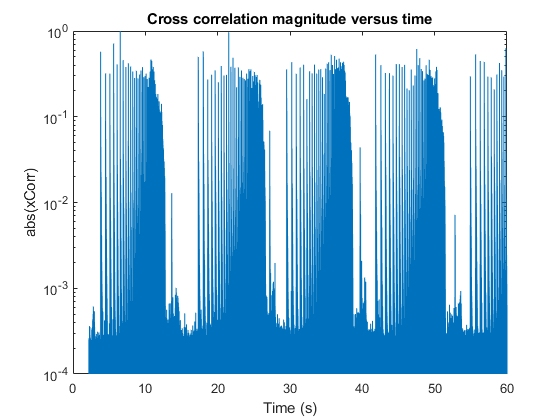

semilogy(tCorr,abs(xCorr))
ylim([1e-4,1])
xlabel('Time (s)');ylabel('abs(xCorr)');
title('Cross correlation magnitude versus time')

We see the noise level in the cross correlation is a few e-4 but there can be some extraneous peaks between experiments in a multi-experiment (multi drop) file to avoid. Also, the reverberation time is comparable to the time between bounces for the small bounces near the end of a bounce experiment. Trying to pick up small bounces with small time between peaks permitted and small peak heights permitted can result in picking up reverberation peaks from large amplitude initial bounces. Findpeaks does not provide for sliding thresholds.

Pick a default threshold to avoid reverberation peaks but find as many small final bounces as possible.

threshold = 1e-2;

Pick a default minimum distance between peaks.

minpeakdistance=0.075;

Pick a default minimum peak height.

minpeakheight=.05;

Pick a default minimum peak prominence (height above neighbor valleys).

minpeakprominence=threshold;

Tune these choices for different files.

if ifile==1
   threshold = 1e-2;
   minpeakheight=.015;
   minpeakdistance=0.15;
   minpeakprominence=threshold;
end
if ifile==2
   threshold = .5e-2;
   minpeakheight=.015;
   minpeakdistance=0.02;
   minpeakprominence=threshold;
end
if ifile==3
   threshold = .5e-2;
   minpeakheight=.08;
   minpeakdistance=0.05;
   minpeakprominence=threshold;
end

**Try this**: Open the next figure in a separate window and zoom to explore how well it is working. Play with peak finding parameters to optimize.  Change the Threshold, MinPeakHeight, MinPeakDistance, and MinPeakProminence values to match your data.

Calling `findpeaks` without catching output will produce a plot.

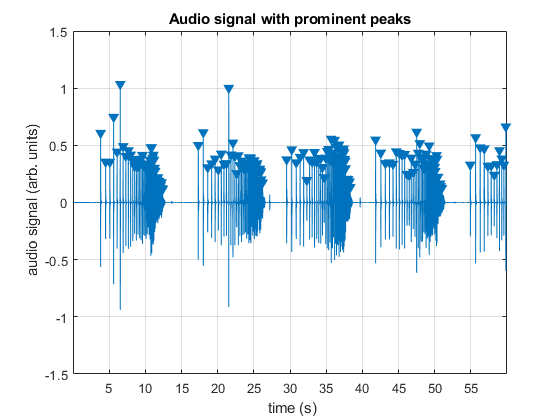

findpeaks(xCorr,tCorr,'Threshold',threshold,...
    'MinPeakHeight',minpeakheight,'MinPeakDistance',minpeakdistance)
xlabel(' time (s)');ylabel(' audio signal (arb. units)')
title('Audio signal with prominent peaks')

Repeat, catching `peaks`=peak values of xcorr, and `locs`= times.

figure
[peaks,locs]=findpeaks(xCorr,tCorr,'Threshold',threshold,...
    'MinPeakHeight',minpeakheight,'MinPeakDistance',minpeakdistance);

### Compute coefficient of restitution from ratios of bounce time intervals.

Neglecting air drag and other effects, bounce time interval is twice the time to reach the highest point, tbounce= 2v_0/g, with v_0 the speed at the start and end of the bounce. The coefficient of restitution is the ratio of speeds in successive bounces. Hence, the ratio of bounce times gives equals the coefficient of restitution. 

Subtract the first bounce time from all bounce times.

tbounce=locs-locs(1);
tbounce=tbounce(2:end);

Plot the times of the bounces, relative to the first bounce, as a function of bounce number.

plot(tbounce,'x')
xlabel('Bounce number');ylabel('Time (s)')
title('Bounce times')

Add model assuming drop from a height of 1 m with some constant coefficient of restitution.

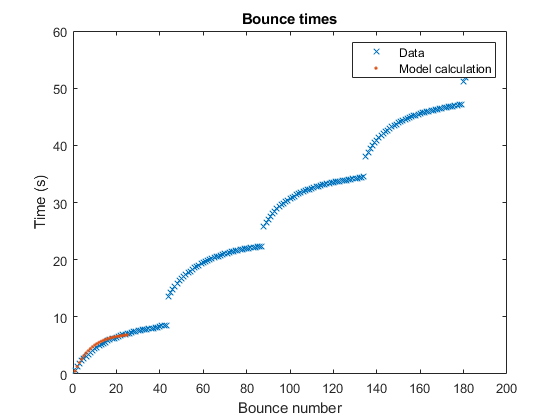

g=9.8;
h=1.00;
v_0=sqrt(2*g*h);
t_0=2*v_0/g;
C=.88;
tpredict=zeros(1,25);
for ibounce=1:25
    tpredict(ibounce)=v_0/(g*C)+(2*v_0/g)*C*(1-C^(ibounce-1))/(1-C);
end
hold on
plot(tpredict,'.'); legend('Data','Model calculation')

Get time differences between all successive bounces.

dt=diff(tbounce);

Compute ratios of sucessive time differences.

dt2=dt(2:end);dt1=dt(1:end-1);
dtratio=(dt2./dt1);

Time intervals between experiments give erroneous results. Mask these out.

mask = dtratio<1&dtratio>0.5;
good_dtratio=dtratio(mask);
good_dt1=dt1(mask);

Plot filtered bounce interval ratios.

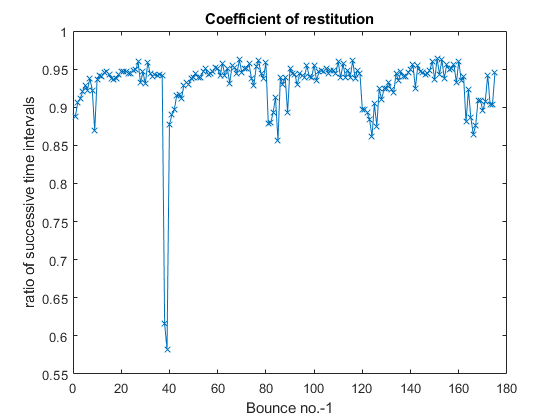

figure
plot(good_dtratio,'x-')
xlabel('Bounce no.-1');ylabel('ratio of successive time intervals')
title('Coefficient of restitution')

Create mask to eliminate some points which appear erroneous.

mask1=ones(1,length(dtratio(mask)));
if ifile==1
    mask1(33:44)=0;
end
mask1=logical(mask1);

Plot coefficient of restitution versus bounce time interval (proportional to bounce velocity and bounce height).

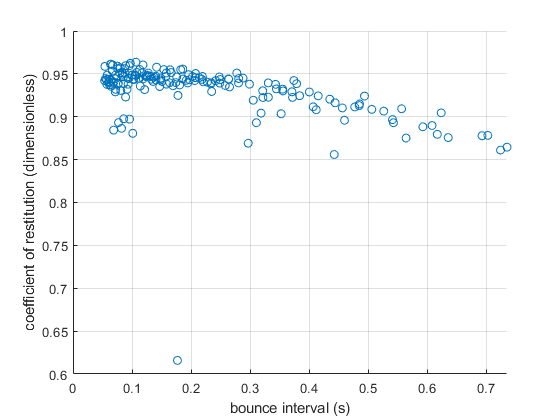

scatter(good_dt1(mask1),good_dtratio(mask1))
xlabel('bounce interval (s)');ylabel('coefficient of restitution (dimensionless)')
xlim([0.0,min(1.0,max(good_dt1(mask1)))]);ylim([0.6,1])
grid on

We see evidence for an apparent decrease of coefficient of restitution with relative velocity of ball and surface.

The template is a few ms long while the time intervals are 50-700 ms. We see noise in the time interval ratios which may concern our template matching a variable physical acoustic signal. There are also clearly outliers to be investigated.

The terminal speed for a ping pong ball is estimated to be 9.4 m/s. The impact speed for a 1 m drop is naively given by $v=\sqrt{2gh}=4$m/s. The ratio of the drag force to the gravitational force is 20% at this speed. On the other hand, at a speed of 1 m/s, the drag force is a factor of 16 smaller if variation in the drag coefficient with speed is neglected. The effect of drag must be considered before ascribing the apparent decrease of COR with velocity to impact mechanics. (See [Aerodynamic Effects in a Dropped Ping-Pong Ball Experiment](https://www.ijee.ie/articles/Vol19-4/IJEE1433.pdf).) 

### References:

[How ping pong balls are made](https://www.youtube.com/watch?v=g_oBgkMCSS8).